## Initialize: where do you want the results to be stored?

uid = 'sabina';
eid = 'ad6';

pathdata = ['D:/' uid '/' eid]

pathdata = 'D:/sabina/ad6'

if isempty(dir([pathdata '/properties/']))
    mkdir([pathdata '/properties/']);
end

## MIP of "standard" microangiogram ROI

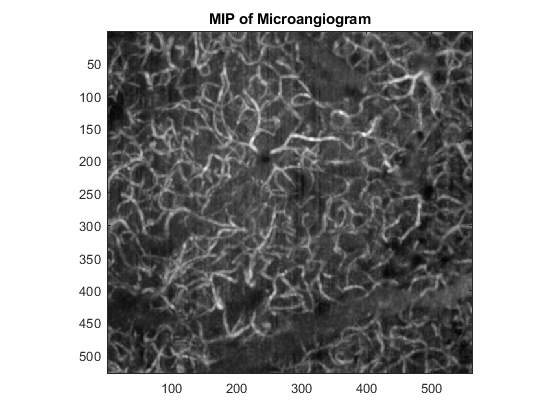

mip = squeeze(max(logDD,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray);
axis image;
title('MIP of Microangiogram')


saveas(gcf,[pathdata '/properties/DD_MIP.png'])

## MIP of enhanced microangiogram ROI

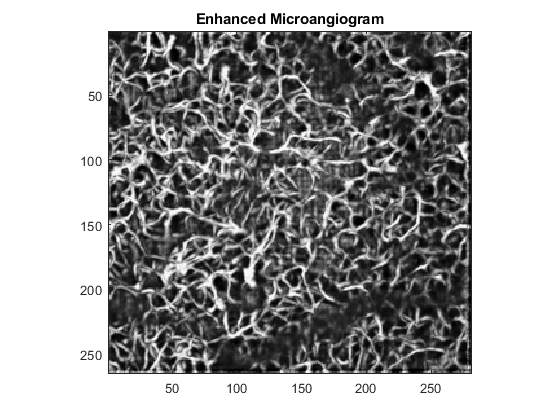

mip = squeeze(max(V,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray);
axis image;
title('Enhanced Microangiogram')


saveas(gcf,[pathdata '/properties/EnhancedMIP.png'])

## MIP of segmentation

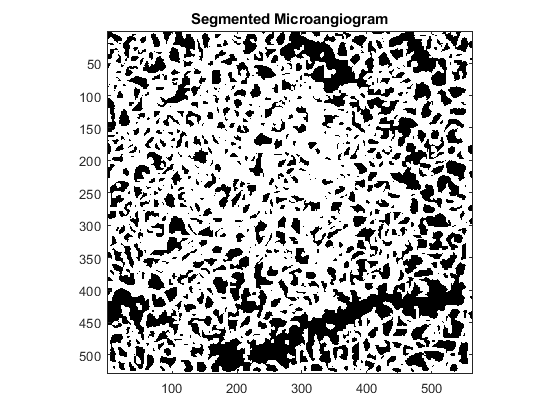


mip = squeeze(max(res,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray);
axis image;
title('Segmented Microangiogram')

saveas(gcf,[pathdata '/properties/Segmentation.png'])

## MIP of vasculature with each vessel shown with a different color

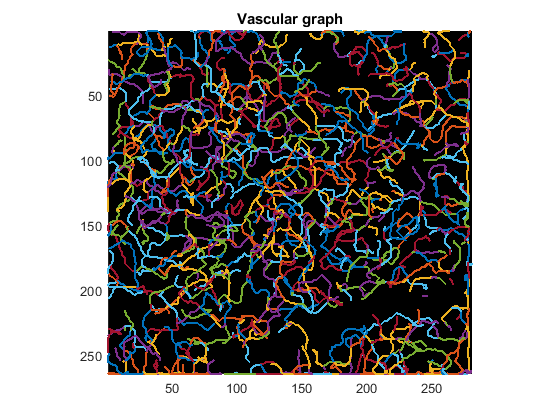


figure;
hold on
for i = 1:length(S)
plot(S{i}(:,3), S{i}(:,2), 'linewidth', 1.5)
end
axis image
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
ax = gca;
ax.YDir = 'reverse';
title('Vascular graph')

saveas(gcf,[pathdata '/properties/VascularGraph.png'])

## MIP showing vessels colored according to vessel tortuosity

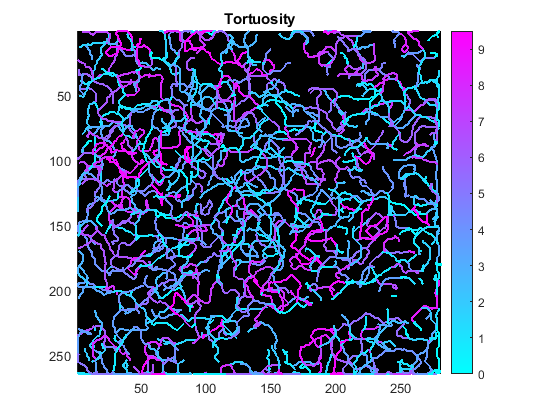

tort_uniq = unique(tort);
c = cool(length(tort_uniq));

figure; 

hold on
for i = 1:length(S)
    ind = find(tort(i) == tort_uniq);
    plot(S{i}(:,3), S{i}(:,2), 'linewidth', 1.5, 'color', c(ind,:))
end
axis image
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
ax = gca;
ax.YDir = 'reverse';
colormap(c);
caxis([min(tort) max(tort)])
h = colorbar;
colorbar
title('Tortuosity')
saveas(gcf,[pathdata '/properties/TortuosityGraph.png'])

## Distribution of vessel tortuosity

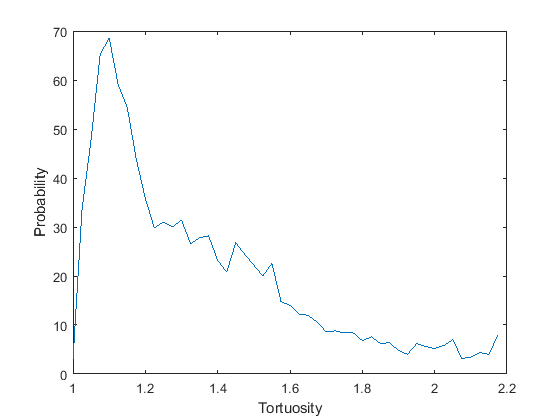

figure;
[ht, nt] = histcounts(tort(fl>2), 1:0.025:2.2);
ht = smooth(ht,5);
plot(nt(1:end-1), ht);
xlabel('Tortuosity')
ylabel('Probability')
saveas(gcf,[pathdata '/properties/TortuosityDistribution.png'])

## MIP showing vessels colored according to vessel diameter

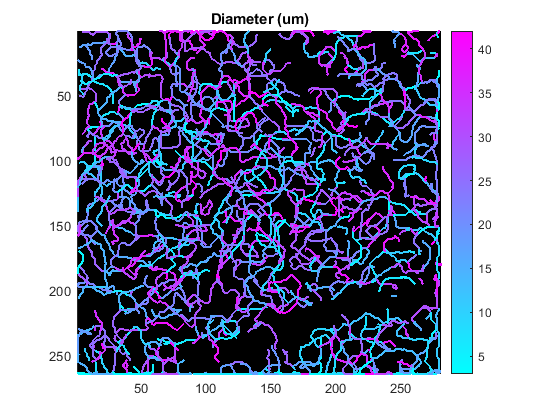

d_uniq = unique(D);
c = cool(length(d_uniq));

[hd, nd] = histcounts(D(full_l>6), 3:50);
hd = smooth(hd,5);

figure;
hold on
for i = 1:length(S)
    ind = find(D(i) == d_uniq);
    plot(S{i}(:,3), S{i}(:,2), 'linewidth', 1.5, 'color', c(ind,:))
end
axis image
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
ax = gca;
ax.YDir = 'reverse';
colormap(c);
caxis([min(D) max(D)])
h = colorbar;
colorbar
title('Diameter (um)')
saveas(gcf,[pathdata '/properties/DiameterGraph.png'])

## Distribution of vessel lengths

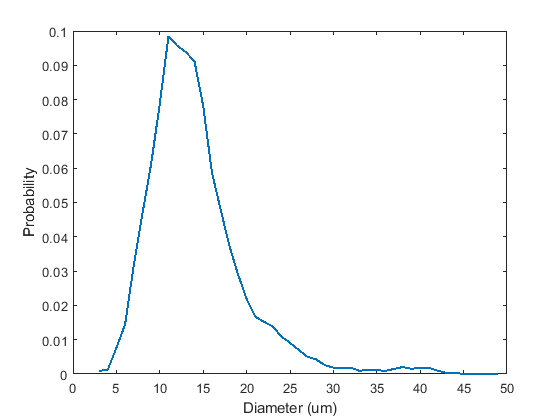

figure;
plot(nd(1:end-1), hd/trapz(hd), 'linewidth', 1.5)
xlabel('Diameter (um)')
ylabel('Probability')
saveas(gcf,[pathdata '/properties/DiameterDistribution.png'])

## MIP showing vessels colored according to vessel length

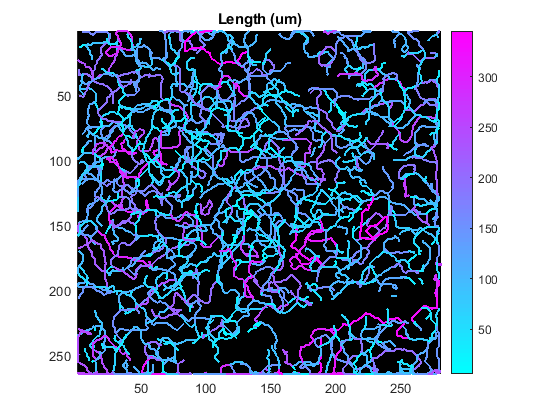


full_uniq = unique(full_l);
c = cool(length(full_uniq));

[hl, nl] = histcounts(full_l(full_l>6), 2.5:5:200);
hl = smooth(hl,10);

figure; 
hold on
for i = 1:length(S)
    ind = find(full_l(i) == full_uniq);
    plot(S{i}(:,3), S{i}(:,2), 'linewidth', 1.5, 'color', c(ind,:))
end
axis image
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
ax = gca;
ax.YDir = 'reverse';

colormap(c);
caxis([min(full_l) max(full_l)])
h = colorbar;
title('Length (um)')
saveas(gcf,[pathdata '/properties/LengthGraph.png'])

## Distribution of vessel lengths

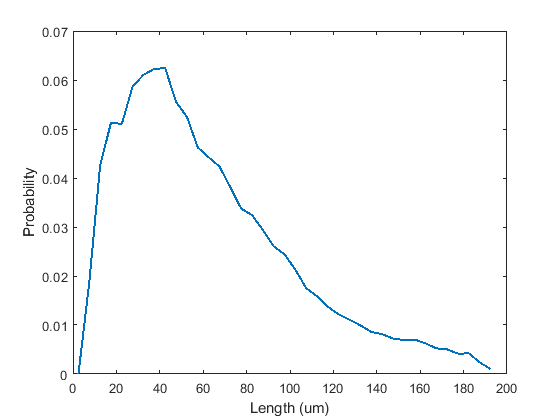

figure;
plot(nl(1:end-1), hl/trapz(hl), 'linewidth', 1.5)
xlabel('Length (um)')
ylabel('Probability')
saveas(gcf,[pathdata '/properties/LengthDistribution.png'])

## Select ROI for 3D visualization

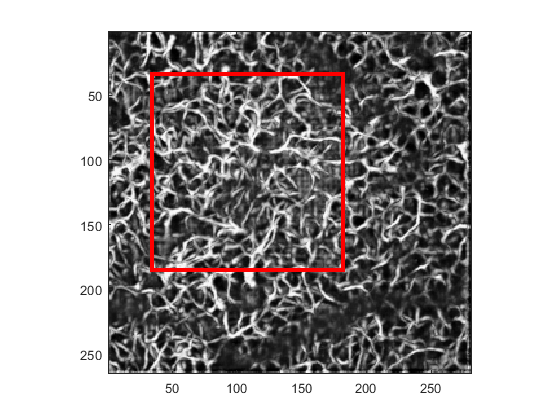

Select_ROI_figure;

mip = squeeze(max(V,[],1));
figure(1); imagesc(squeeze((mip)))
colormap(gray)
axis image
title('selected ROI for 3D visualization')
hold on; rectangle('Position', [x1, y1, x2-x1, y2-y1], 'EdgeColor','r', 'LineWidth', 3);
saveas(gcf,[pathdata '/properties/SmallAreaChosen.png'])


small3D;

## 3D visualization of selected subsection 

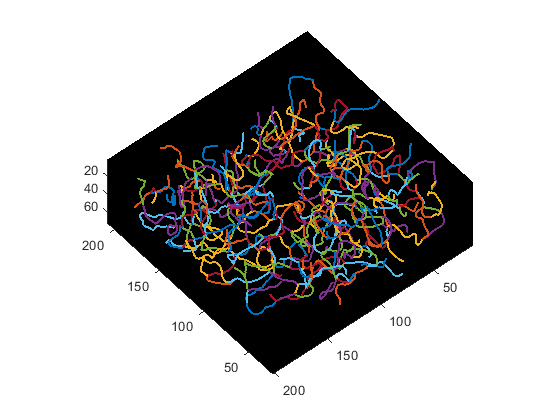

figure; hold on; 
for i = 1:length(S_small)
ind = find(D_small(i) == ds_uniq);
plot3(smooth(S_small{i}(:,3)), smooth(S_small{i}(:,2)), smooth(S_small{i}(:,1)),'linewidth', 1.5)
end
ax = gca;
ax.YDir = 'reverse';
ax.ZDir = 'reverse';
axis image
view(140,50)
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
title(' 3D visualization')
saveas(gcf,[pathdata '/properties/small3D.png'])

## 3D visualization of selected vessels colored by diameter

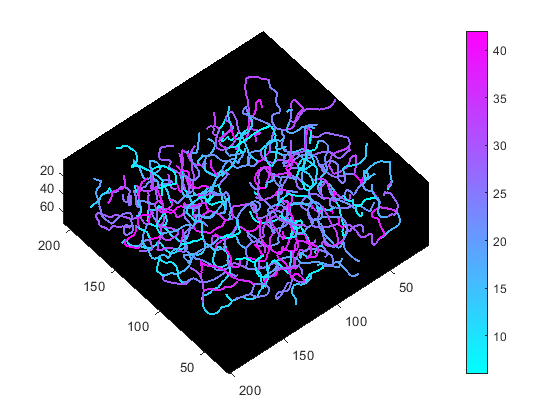

c = cool(length(ds_uniq));
figure; hold on; 
for i = 1:length(S_small)
ind = find(D_small(i) == ds_uniq);
plot3(smooth(S_small{i}(:,3)), smooth(S_small{i}(:,2)), smooth(S_small{i}(:,1)),'linewidth', 1.5, 'color', c(ind,:))
end
ax = gca;
ax.YDir = 'reverse';
ax.ZDir = 'reverse';
axis image
view(140,50)
colormap(c);
caxis([min(D_small) max(D_small)])
colorbar
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
title('Diameter')
saveas(gcf,[pathdata '/properties/small3D_diameter.png'])

## 3D visualization of selected vessels colored by length

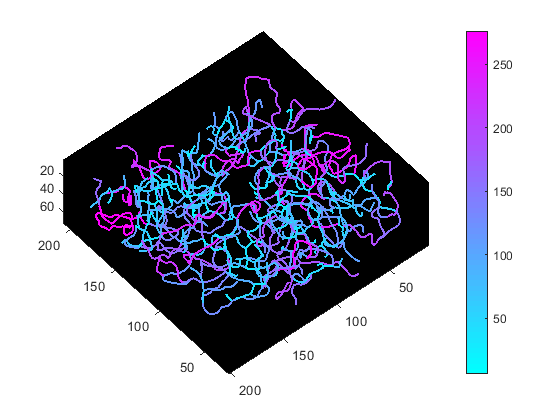


c = cool(length(ls_uniq));
figure; hold on; 
for i = 1:length(S_small)
ind = find(length_small(i) == ls_uniq);
plot3(smooth(S_small{i}(:,3)), smooth(S_small{i}(:,2)), smooth(S_small{i}(:,1)),'linewidth', 1.5, 'color', c(ind,:))
end
ax = gca;
ax.YDir = 'reverse';
ax.ZDir = 'reverse';
axis image
view(140,50)
colormap(c);
caxis([min(length_small) max(length_small)])
colorbar
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
title('Length')
saveas(gcf,[pathdata '/properties/small3D_length.png'])

## 3D visualization of selected vessels colored by tortuosity

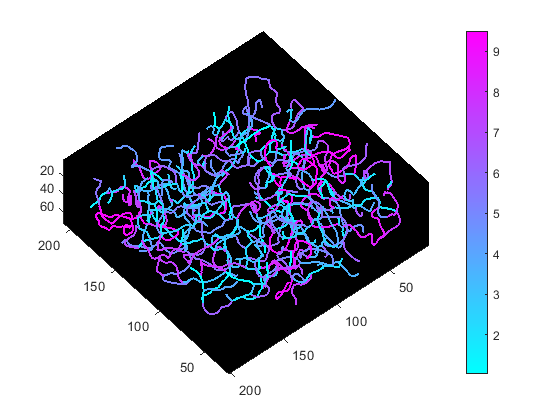

c = cool(length(ts_uniq));
figure; hold on; 
for i = 1:length(S_small)
ind = find(tort_small(i) == ts_uniq);
plot3(smooth(S_small{i}(:,3)), smooth(S_small{i}(:,2)), smooth(S_small{i}(:,1)),'linewidth', 1.5, 'color', c(ind,:))
end
ax = gca;
ax.YDir = 'reverse';
ax.ZDir = 'reverse';
axis image
view(140,50)
colormap(c);
caxis([min(tort_small) max(tort_small)])
colorbar
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
title('Tortuosity')
saveas(gcf,[pathdata '/properties/small3D_tort.png'])

## Distribution of branching orders

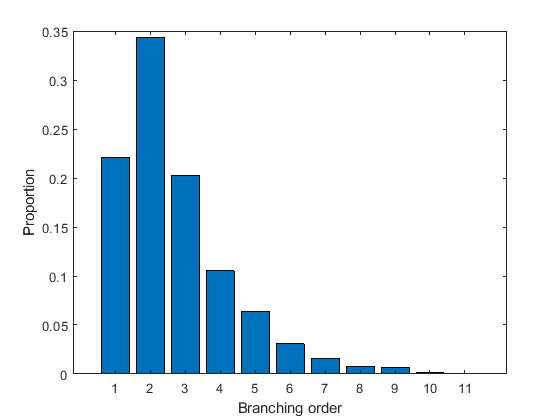

l = cellfun(@(x) length(x), B);
figure; bar(l/sum(l))
xlabel('Branching order')
ylabel('Proportion')
saveas(gcf,[pathdata '/properties/branchingorder.png'])